# Data analysis of localization confidence

- Compares confidence between unimodal and bimodal conditions

clear; clc; close all;
sub_slc     = 6;
ses_slc     = 1:2;

% manage path
cur_dir      = pwd;
[project_dir, ~]= fileparts(fileparts(cur_dir));
out_dir      = fullfile(cur_dir, 's1Fig');
addpath(genpath(fullfile(project_dir,'func')))
data_dir     = fullfile(project_dir, 'data','biLoc');
if ~exist(out_dir,'dir') mkdir(out_dir); end

% organize data
[bi_resp, bi_conf, bi_err, ExpInfo] = org_data(sub_slc,ses_slc,'biLoc');
[uni_resp, uni_conf, uni_err, uniExpInfo, ~, ScreenInfo] = org_data(sub_slc,[],'uniLoc'); % condition (A,V1,V2) x loc (4) x rep

% conditions
seq         = ExpInfo.randAVIdx;
audIdx      = ExpInfo.audIdx;
visIdx      = ExpInfo.visIdx;
cueIdx      = ExpInfo.cueIdx;
visReliIdx  = ExpInfo.visReliIdx;
num_rep     = ExpInfo.nRep;
deg_per_px  = rad2deg(atan(170 / 2 / ExpInfo.sittingDistance)) .* 2 / ScreenInfo.xaxis;cue_label   = {'Post-cue: A','Post-cue: V'};
rel_label   = {'High visual reliability','Low visual reliability'};
aud_locs    = ExpInfo.speakerLocVA(ExpInfo.audIdx);
remapped_vis_locs = ExpInfo.targetPixel .* deg_per_px;

%% reorganize uni and bi confidence
uni_pconf = mean(mean(uni_conf,3),2);
% organize bi-confidence by discrepancy
[conf_by_diff, abs_diff] = org_by_diffs(bi_conf, aud_locs); % {diff} cue x reliability x rep 

%% reorganize ventriloquist effect
mean_uni_resp = mean(uni_resp, 3); % condition (A,V1,V2) x loc (4) x rep
loc_a = repmat(mean_uni_resp(1,:)', [1, numel(remapped_vis_locs)]);
remap_loc_v = repmat(remapped_vis_locs, [numel(aud_locs), 1]);
% Use the real (i.e., biased) visual localization in unimodal task
loc_v1 = repmat(mean_uni_resp(2,:), [numel(aud_locs), 1]); 
loc_v2 = repmat(mean_uni_resp(3,:), [numel(aud_locs), 1]);

% reshape into dimensions of bi
uni_loc(:,:,1,1:2) = repmat(loc_a, [1,1,1,2]);
% uni_loc(:,:,1,1:2) = repmat(remap_loc_v, [1,1,1,2]);
uni_loc(:,:,2,1) = repmat(loc_v1, [1,1,1,1]);
uni_loc(:,:,2,2) = repmat(loc_v2, [1,1,1,1]);

% loc at uni minus loc at bi
ve = uni_loc - mean(bi_resp, 5);
std_ve = std(bi_resp,[], 5);

% diff x cue x reliability
[ve_by_raw_diff, raw_diff] = org_by_raw_diffs_4D(ve, aud_locs);
[std_ve_by_raw_diff, ~] = org_by_raw_diffs_4D(std_ve, aud_locs);

## Plot set up

lw = 2;
fontSZ = 15;
titleSZ = 20;
dotSZ = 80;
clt = [30, 120, 180; % blue
    227, 27, 27;  % dark red
    repmat(125, 1, 3)]./255; % gray
%     251, 154, 153]./255; % light red


## Sanity check: localization response

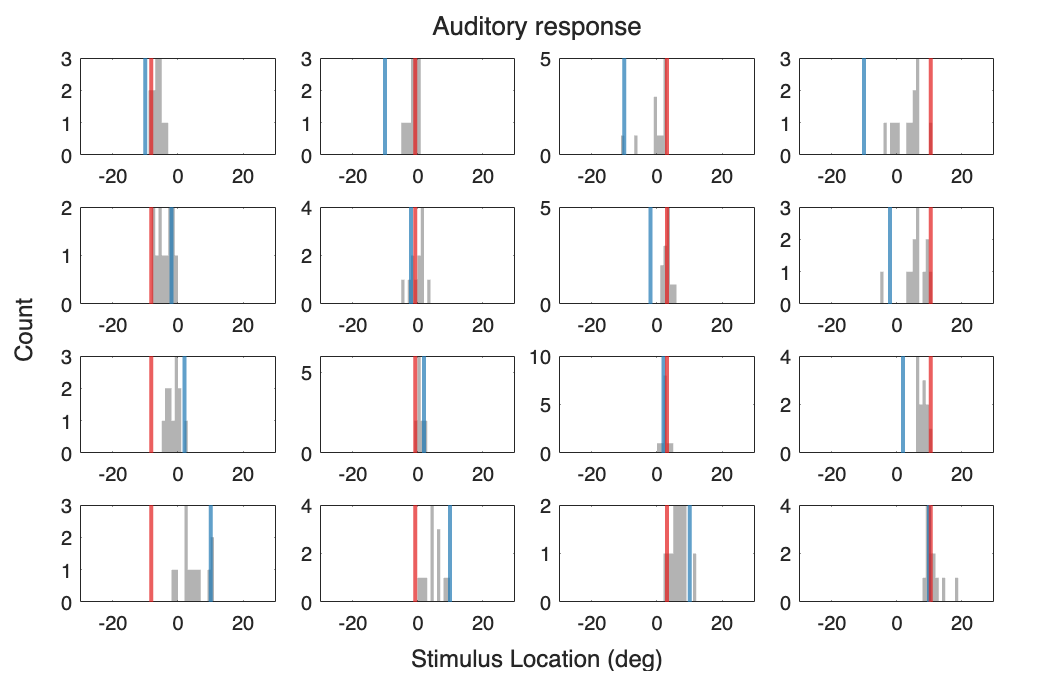

figure
set(gcf, 'Position', get(0, 'Screensize')); hold on
t = tiledlayout(4, 4);
title(t, 'Auditory response')
xlabel(t, 'Stimulus Location (deg)');
ylabel(t, 'Count');
t.TileSpacing = 'compact';
t.Padding = 'compact';
% Loop over each auditory index
for a = 1:length(audIdx)
    % Loop over each visual index
    for v = 1:length(visIdx)
         curr_resp = squeeze(bi_resp(a, v, 1, 1, :));
         nexttile
         h = histogram(curr_resp, numel(curr_resp),'BinWidth',1);
         h.FaceColor = repmat(0.5, 1, 3); 
         h.EdgeColor = 'none';

         xline(aud_locs(a),'LineWidth',lw,'Color',clt(1,:))
         xline(remapped_vis_locs(v),'LineWidth',lw,'Color',clt(2,:))

         xlim([-30, 30])
    end
end

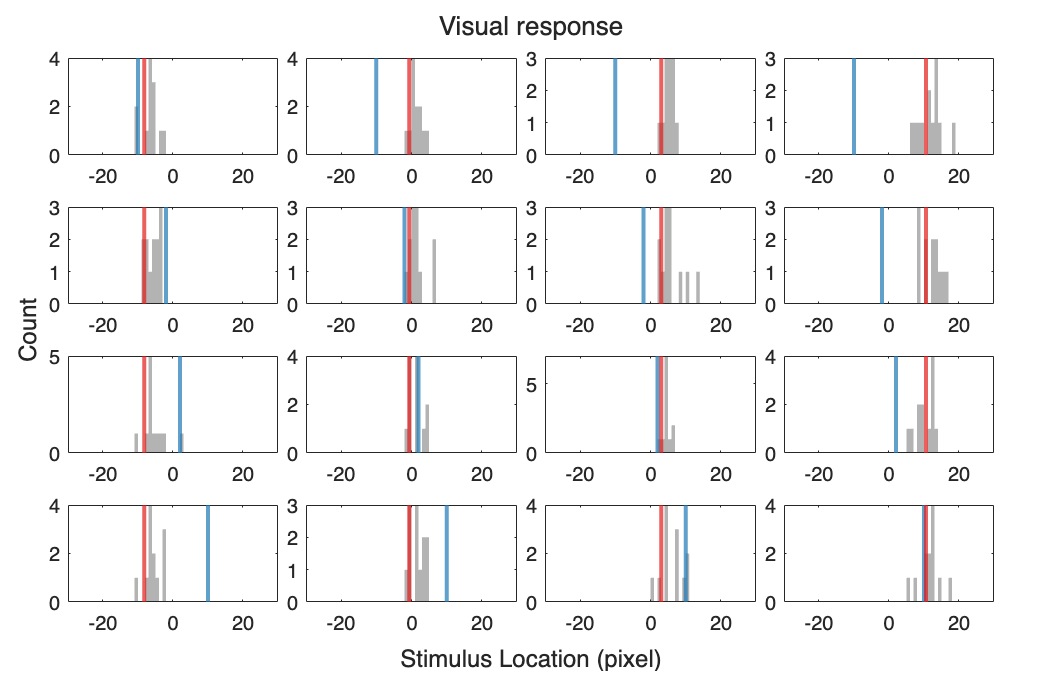



figure
set(gcf, 'Position', get(0, 'Screensize')); hold on
t = tiledlayout(4, 4);
title(t, 'Visual response')
xlabel(t, 'Stimulus Location (pixel)');
ylabel(t, 'Count');
t.TileSpacing = 'compact';
t.Padding = 'compact';
% Loop over each auditory index
for a = 1:length(audIdx)
    % Loop over each visual index
    for v = 1:length(visIdx)
         curr_resp = squeeze(bi_resp(a, v, 2, 2, :));
         nexttile
         h = histogram(curr_resp, numel(curr_resp),'BinWidth',1);
         h.FaceColor = repmat(0.5, 1, 3); 
         h.EdgeColor = 'none';

         xline(aud_locs(a),'LineWidth',lw,'Color',clt(1,:))
         xline(remapped_vis_locs(v),'LineWidth',lw,'Color',clt(2,:))

         xlim([-30, 30])
    end
end

## Is confidence modulated by cue discrepancy and cue reliability?

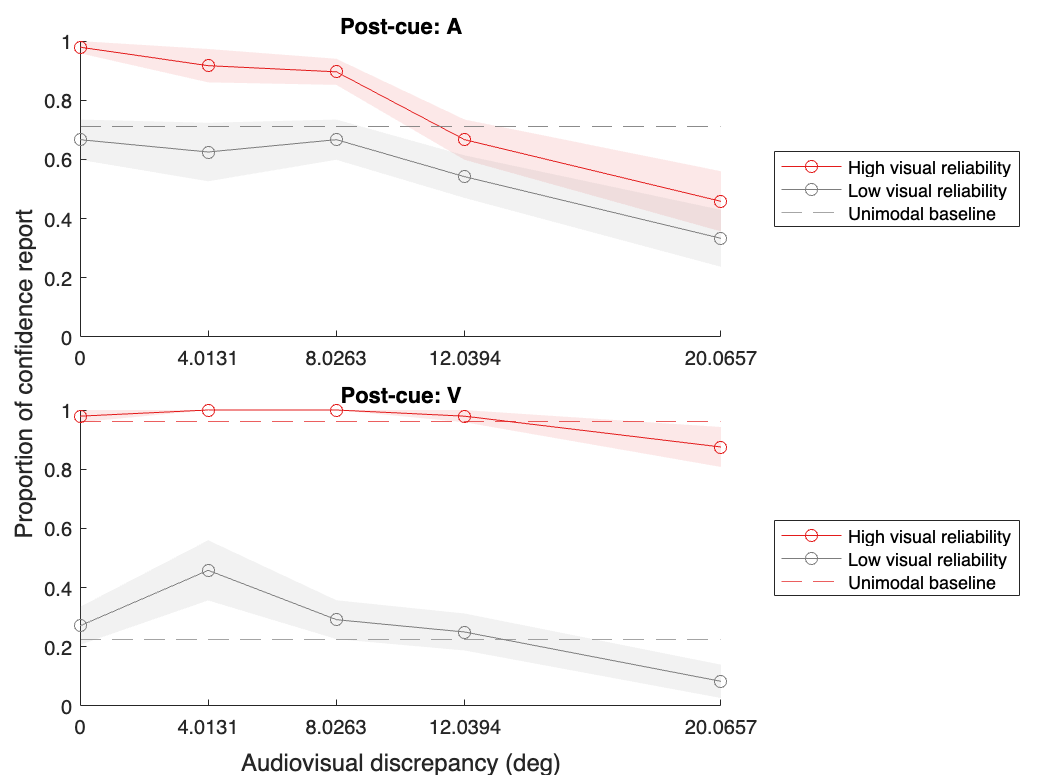

figure; hold on 

t = tiledlayout(2, 1);
xlabel(t, 'Audiovisual discrepancy (deg)');
ylabel(t, 'Proportion of confidence report');
t.TileSpacing = 'compact';
t.Padding = 'compact';

for cue = 1:numel(cueIdx)
    nexttile
    title(cue_label{cue})
    hold on
    for rel = 1:numel(visReliIdx)
        [mean_p, sd_p] = deal(NaN(1, numel(abs_diff)));
        for diff = 1:numel(abs_diff)
            est = squeeze(conf_by_diff{diff}(cue, rel, :))';
            p = sum(est)/numel(est);
            mean_p(diff) = p;
            sd_p(diff) = sqrt((p*(1-p))/numel(est));
        end
        plot(abs_diff, mean_p,'-o', 'Color',clt(rel+1,:))
        patch([abs_diff, fliplr(abs_diff)], ...
            [mean_p - sd_p, fliplr(mean_p + sd_p)], ...
            clt(rel+1,:),'EdgeColor','none','FaceAlpha',0.1, ...
            'HandleVisibility', 'off')
        
        if cue == 1
            yline(uni_pconf(1),'--','Color',repmat(0.5,1,3))
        else
            yline(uni_pconf(rel+1),'--','Color',clt(rel+1,:))
        end
        
        ylim([0, 1])
        xlim([min(abs_diff), max(abs_diff)])
    end
    xticks(abs_diff)
    legend({'High visual reliability','Unimodal baseline','Low visual reliability'}, 'Location', 'eastoutside');
end

## Ventriloquist effect

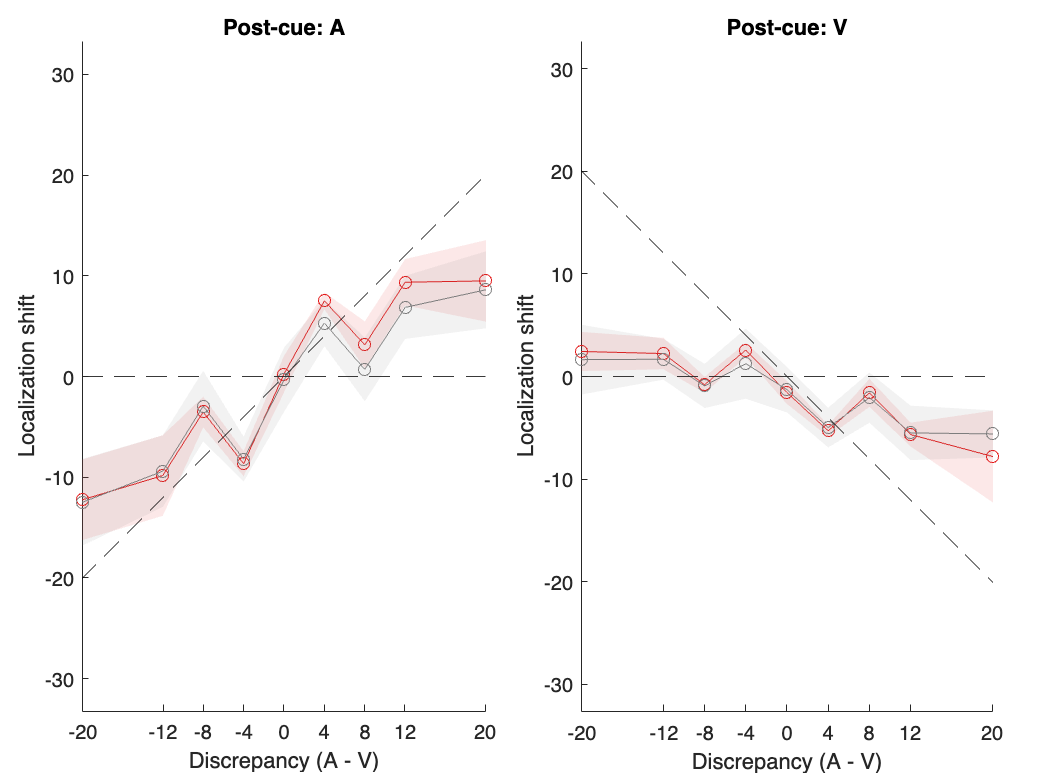

figure
t = tiledlayout(1,2);
% xlabel(t, 'Audiovisual discrepancy (pixel)');
% ylabel(t, 'Proportion of confidence report');
t.TileSpacing = 'compact';
t.Padding = 'compact';

for cue = 1:numel(cueIdx)
    nexttile
    title(cue_label{cue})
    axis equal
    hold on
    for rel = 1:numel(visReliIdx)

        plot(raw_diff, ve_by_raw_diff(:, cue, rel),'-o', 'Color',clt(rel+1,:));
        patch([raw_diff, fliplr(raw_diff)], ...
            [ve_by_raw_diff(:, cue, rel)' - std_ve_by_raw_diff(:,cue, rel)', ...
            fliplr(ve_by_raw_diff(:, cue, rel)' + std_ve_by_raw_diff(:,cue, rel)')],...
            clt(rel+1,:),'EdgeColor','none','FaceAlpha',0.1, ...
            'HandleVisibility', 'off');

        yline(0,'--')

        if cue == 1
        plot(raw_diff, raw_diff,'k--')
        else 
        plot(raw_diff, -raw_diff,'k--')
        end
     


% 
% 
%         [mean_ve, sd_ve] = deal(NaN(1, numel(raw_diff)));
%         for diff = 1:numel(raw_diff)
%             i_ve = squeeze(ve_by_diff{diff}(cue, rel, :))';
%             mean_ve(diff) = mean(i_ve);
%             sd_ve(diff) = std(i_ve);
%         end
% 
%         plot(raw_diff(cue,:), mean_ve,'-o', 'Color',clt(rel+1,:))
%         hold on
%         
%         patch([raw_diff(cue,:), fliplr(raw_diff(cue,:))], ...
%             [mean_ve - sd_ve, fliplr(mean_ve + sd_ve)], ...
%             clt(rel+1,:),'EdgeColor','none','FaceAlpha',0.1, ...
%             'HandleVisibility', 'off')
%         plot(linspace(min(raw_diff(cue,:)),max(raw_diff(cue,:)),10),linspace(min(raw_diff(cue,:)),max(raw_diff(cue,:)),10),'--')
%         xlim([min(raw_diff(cue,:)), max(raw_diff(cue,:))])
    end
    xticks(sort(round(raw_diff)))
    ylabel('Localization shift')
    xlabel('Discrepancy (A - V)')
    % legend([rel_label{1} ], 'Location', 'northeast');
end